# Carandini et al. 1997

## MAKE STIMULUS

t = 0.001 : 0.001 : 1; t_lth = length(t);
% stimulus
s = zeros(1, t_lth); s(t>0.2 & t<0.7) = 1;


## LINEAR RESPONSES

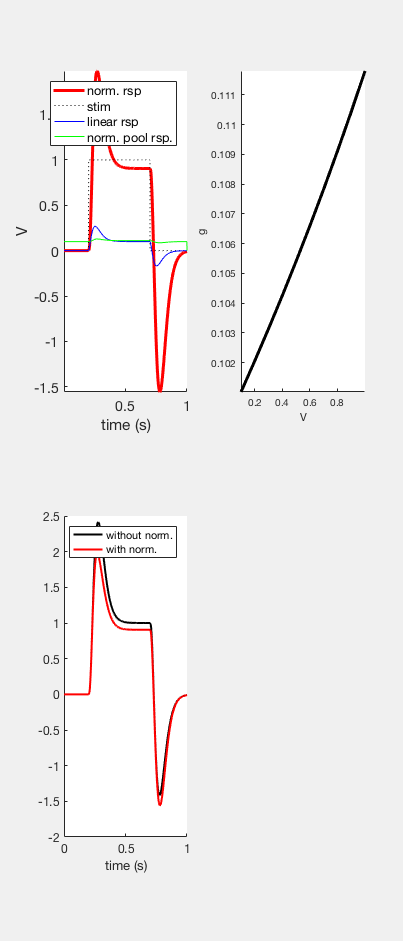

tau = 0.020;

irf1 = t.*exp(-t./tau); irf1 = irf1./sum(irf1);
irf2 = t.*exp(-t./(tau*1.5)); irf2 = irf2./sum(irf2);
w = .9;
irf = irf1 - w*irf2;
I = conv(s, irf); I = I(1 : t_lth);

C = 2; % capacitance
g = 0.05; % Siemens

delta_V = 0;
V       = zeros(1, t_lth);
V1      = zeros(size(V));

% firing rate;
% since there is no negative response here, so that I assume the firing rate is the same as the potential
g0 = 0.1;
k  = 0.2; % determines the effectiveness of the normalization pool
compute_g = @(g0, k, V) g0./sqrt(1 - k .* V);

example_g = compute_g(g0, k, 0.1 : 0.1 : 1);

g = zeros(1, t_lth);

% compute the change in potential
for it = 1 : t_lth - 1
    g(it) = compute_g(g0, k, V(it));
    delta_V   = (I(it) - g(it) * V(it))/C;
    V(it + 1) = V(it) + delta_V;
    
    % with fixed g, so just a linear response
    g1 = g0;
    delta_V1   = (I(it) - g1 * V1(it))/C;
    V1(it + 1) = V1(it) + delta_V1;
end

figure (1), clf
subplot(2, 2, 1)
plot(t, V, 'r-', 'linewidth', 3), hold on,
plot(t, s, 'k:'), plot(t, I, 'b')
plot(t, g, 'g-'), legend('norm. rsp', 'stim', 'linear rsp', 'norm. pool rsp.')
xlabel('time (s)'), ylabel('V'), box off, set(gca, 'fontsize', 14), axis tight

subplot(2, 2, 2), plot(0.1 : 0.1 : 1, example_g, 'k-', 'linewidth', 3), xlabel('V'), ylabel('g'), axis tight, box off

subplot(2, 2, 3),
plot(t, V1, 'k-', 'linewidth', 2), hold on, plot(t, V, 'r-', 'linewidth', 2), box off
legend('without norm.', 'with norm.'), xlabel('time (s)'), set(gca, 'fontsize', 12)

## Compute the normalization response to a step stimulus of a bunch of different contrasts

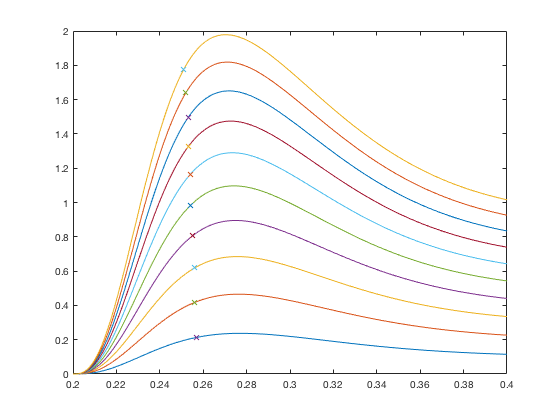

contrast = 0.1 : 0.1 : 1;
n_stim   = length(contrast);

ctr_V = zeros(n_stim, t_lth);

for k = 1 : n_stim
    % compute I
    I = conv(s.*contrast(k), irf);
    I = I(1 : t_lth);
    
    % compute V
    for it = 1 : t_lth - 1
        g(it) = compute_g(g0, 0.2, ctr_V(k, it));
        delta_V   = (I(it) - g(it) * ctr_V(k, it))/C;
        ctr_V(k, it + 1) = ctr_V(k, it) + delta_V;
    end
end

R = max(ctr_V, 0);
figure (2), clf
plot(t, R);
hold on;

% find the first time point that the response reaches 90% of its maximum and plot this
for ii = 1:size(ctr_V,1)
    this_timecourse = R(ii,:);
    [mx,idx] = max(this_timecourse);
    this_timecourse = this_timecourse(1:idx);
    sat = this_timecourse - .9*mx;
    [~, idx] = min(abs(sat));
    plot(t(idx), this_timecourse(idx), 'x')
end
xlim([0.2 0.4])